# Chapter 9 ATAP Exercises

## Gibbs Phenomenon

#### Mason Mault June 2025

Exercises worked

Exercise 9.2: A function with many jumps

Exercise 9.6: Sine intergral

Exercise 9.7: An unresolvable function

Exercise 9.8: Decay away from discontinuity

**Exercise 9.2: A function with many jumps**

Build a 200 degree Chebfun interpolant to the function round(exp(sin(2*pi*x)))

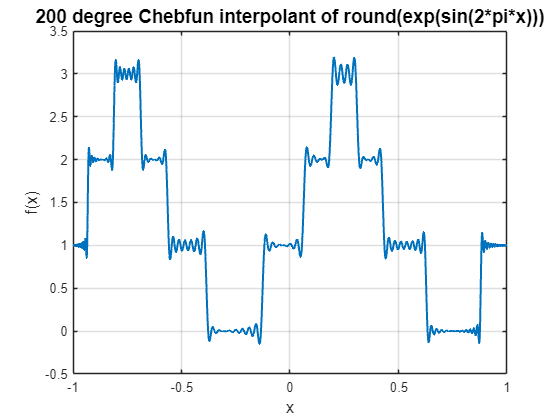

f = chebfun(@(x) round(exp(sin(2*pi*x))), 200);

figure
plot(f, 'LineWidth', 1.5) 
grid on
title('200 degree Chebfun interpolant of round(exp(sin(2*pi*x)))', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('f(x)', 'FontSize', 12)

**Exercise 9.6: Sine intergral**

Construct and plot the sine integral Si(x) for x = 10, 100, and 1000 where


$$\textrm{Si}\left(x\right)=\int_0^x t^{-1} \sin \left(t\right)\textrm{dt}$$


and investigate their degree.

sFunc1 = chebfun(@(t) t.^(-1)*sin(t), [0 10]);
sFunc2 = chebfun(@(t) t.^(-1)*sin(t), [0 100]);
sFunc3 = chebfun(@(t) t.^(-1)*sin(t), [0 1000]);

sInt1 = cumsum(sFunc1, [0 10]); 
length(sInt1)

ans = 24

sInt2 = cumsum(sFunc2, [0 100]);
length(sInt2)

ans = 88

sInt3 = cumsum(sFunc3, [0 1000]);
length(sInt3)

ans = 575

Plot the three functions

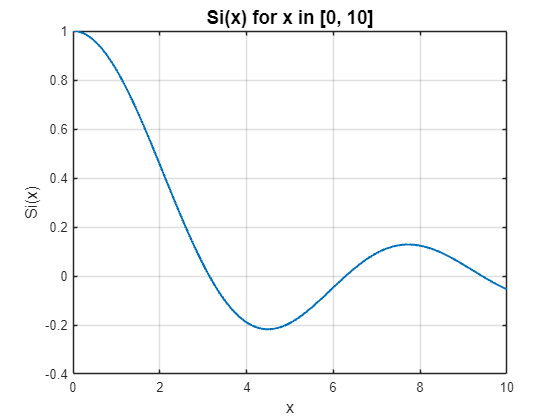

figure
plot(sInt1, 'LineWidth', 1.5) 
grid on
title('Si(x) for x in [0, 10]', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('Si(x)', 'FontSize', 12)

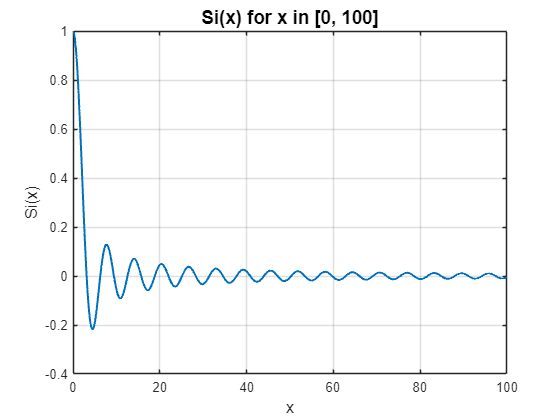

figure
plot(sInt2, 'LineWidth', 1.5) 
grid on
title('Si(x) for x in [0, 100]', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('Si(x)', 'FontSize', 12)

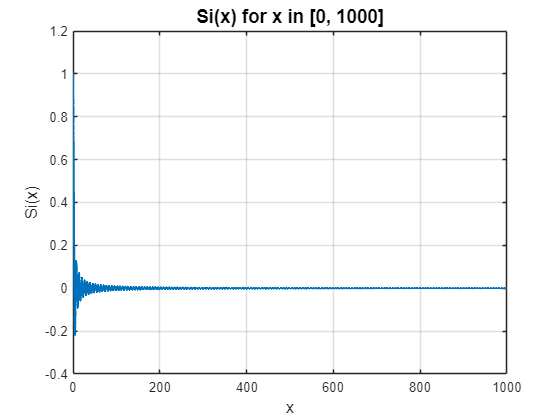

figure
plot(sInt3, 'LineWidth', 1.5) 
grid on
title('Si(x) for x in [0, 1000]', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('Si(x)', 'FontSize', 12)

**Exercise 9.7: An unresolvable function**

When plotting the polynomial interpolant to $g\left(x\right)=\sin \left(\frac{1}{x}\right)$through 100,000 Chebyshev points, it looks as though there is a bug. Redo these plots for 10,000 and 1,000 points and explain.

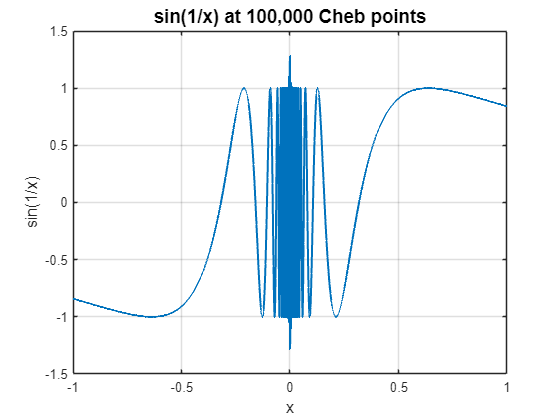

g1 = chebfun(@(x) sin(1/x), 100000);

figure
plot(g1, 'LineWidth', 1.5) 
grid on
title('sin(1/x) at 100,000 Cheb points', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('sin(1/x)', 'FontSize', 12)

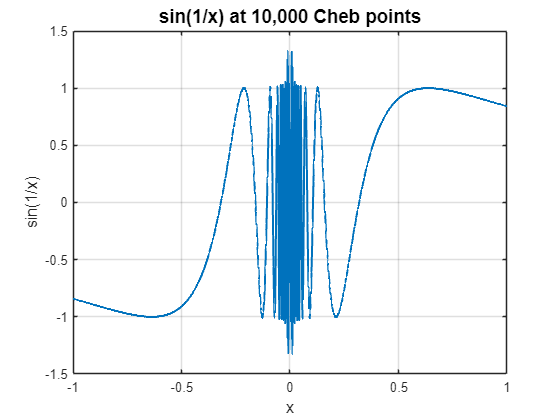

g2 = chebfun(@(x) sin(1/x), 10000);


figure
plot(g2, 'LineWidth', 1.5) 
grid on
title('sin(1/x) at 10,000 Cheb points', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('sin(1/x)', 'FontSize', 12)

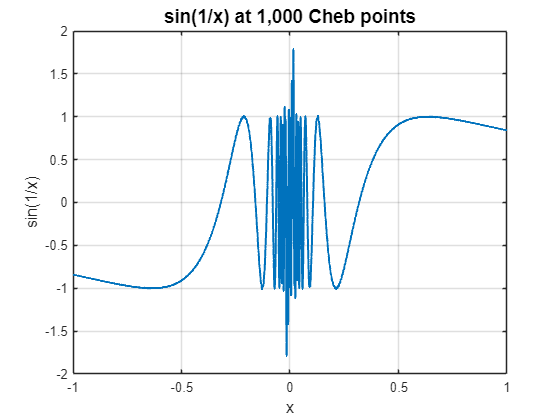

g3 = chebfun(@(x) sin(1/x), 1000);


figure
plot(g3, 'LineWidth', 1.5) 
grid on
title('sin(1/x) at 1,000 Cheb points', 'FontSize', 14, 'FontWeight', 'bold')
xlabel('x', 'FontSize', 12)
ylabel('sin(1/x)', 'FontSize', 12)

Although sin(1/x) has amplitude 1, it oscillates infinitely often near x = 0, and the polynomial interpolants wavenumbers are too low to resolve these oscillations. As more points are included, the degree increases, and the polynomial interpolant is better equipped to capture these rapid oscillations. As n continues to increase, the amplitude approaches 1. 

**Exercise 9.8: Decay away from discontinuity**

Plot the function $h\left(x\right)=\cos \left(7x\right)\sin \left(3x\right)+\mathrm{sign}\left(\sin \left(\frac{x}{2}\right)\right)e^x$ and its interpolating polynomial through 100 Cheb points. 

Then, confirm the algebraic rate of decay of $|f\left(x\right)-p_n \left(x\right)|$ against the function $c\;/\;|x|$, where c is chosen to be the max error over the interval.

hInterp = chebfun(@(x) cos(7*x)*sin(3*x) + sign(sin(x/2))*exp(x), 100);
hTrue = chebfun(@(x) cos(7*x)*sin(3*x) + sign(sin(x/2))*exp(x));

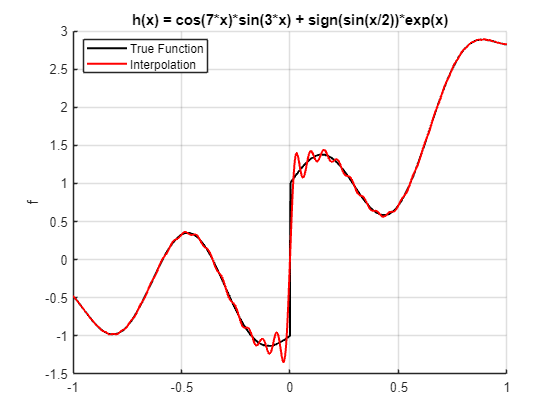

figure
hold on
plot(hTrue, 'k-', 'LineWidth', 1.5);     
plot(hInterp, 'r-', 'LineWidth', 1.5);  

grid on;
ylabel('f');
legend('True Function', 'Interpolation', 'Location', 'Best');
title('h(x) = cos(7*x)*sin(3*x) + sign(sin(x/2))*exp(x)');

Plot the error $|f\left(x\right)-p_n \left(x\right)|$ against c / |x| over [-1, 1], zooming in away from the discontinuities. The actual error falls far below the bound when x is away from the discontinuity.

hErr = hTrue - hInterp;

c = max(hErr);
hErrBound = chebfun(@(x) c / abs(x));

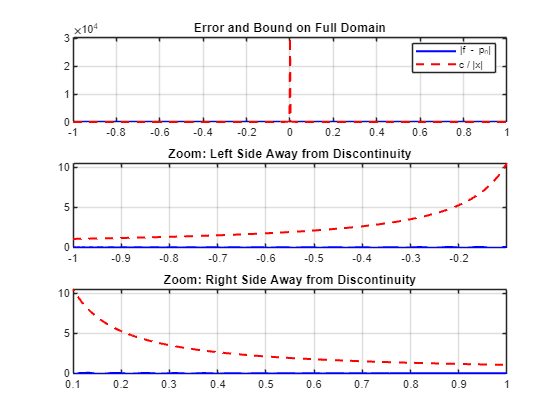

figure
subplot(3,1,1);
plot(hErr, 'b-', 'LineWidth', 1.5);
hold on;
plot(hErrBound, 'r--', 'LineWidth', 1.5);
title('Error and Bound on Full Domain');
legend('|f - p_n|', 'c / |x|');
grid on;

% Zoom left side
subplot(3,1,2);
plot(hErr, 'b-', 'LineWidth', 1.5);
hold on;
plot(hErrBound, 'r--', 'LineWidth', 1.5);
xlim([-1 -0.1]);
title('Zoom: Left Side Away from Discontinuity');
grid on;

% Zoom right side
subplot(3,1,3);
plot(hErr, 'b-', 'LineWidth', 1.5);
hold on;
plot(hErrBound, 'r--', 'LineWidth', 1.5);
xlim([0.1 1]);
title('Zoom: Right Side Away from Discontinuity');
grid on;